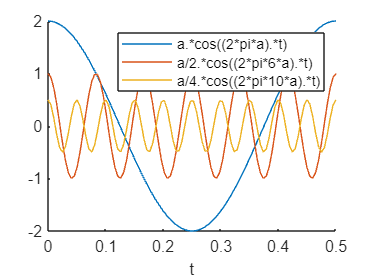

% 1st part in 1st question
a=2;
t = linspace(0,1/a); 
y1=a.*cos((2*pi*a).*t);
y2=a/2.*cos((2*pi*6*a).*t);
y3=a/4.*cos((2*pi*10*a).*t);
hold on
A=plot(t,y1);
B=plot(t,y2);
C=plot(t,y3);
legend([A B C],'a.*cos((2*pi*a).*t)','a/2.*cos((2*pi*6*a).*t)','a/4.*cos((2*pi*10*a).*t)')

xlabel("t")
hold off

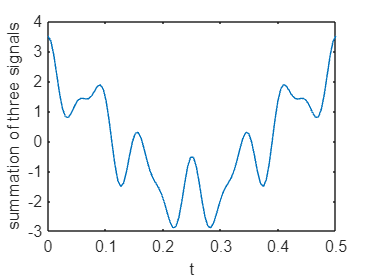

% 2nd part in 1st question
plot(t,(y1+y2+y3))

xlabel("t")
ylabel("summation of three signals")

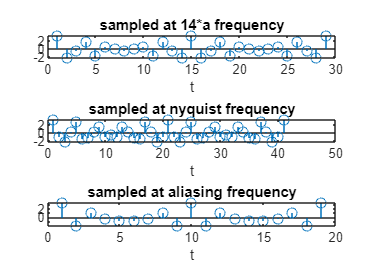

% 3rd part in 1st question
t1=0:1/(14*a):1;
y1=a.*cos((2*pi*5*a).*t1);
y2=a/2.*cos((2*pi*6*a).*t1);
y3=a/4.*cos((2*pi*10*a).*t1);
Y1=y1+y2+y3;
subplot(3,1,1)
stem(Y1)
xlabel("t")
title("sampled at 14*a frequency")
t2=0:1/(20*a):1;
y1=a.*cos((2*pi*5*a).*t2);
y2=a/2.*cos((2*pi*6*a).*t2);
y3=a/4.*cos((2*pi*10*a).*t2);
Y2=y1+y2+y3;
subplot(3,1,2)
stem(Y2)
xlabel("t")
title("sampled at nyquist frequency")
t3=0:1/(9*a):1;
y1=a.*cos((2*pi*5*a).*t3);
y2=a/2.*cos((2*pi*6*a).*t3);
y3=a/4.*cos((2*pi*10*a).*t3);
Y3=y1+y2+y3;
subplot(3,1,3)
stem(Y3)
xlabel("t")
title("sampled at aliasing frequency")

%4th part in 1st question
alpha =1

alpha = 1

freq_1 = 5 * alpha

freq_1 = 5

freq_2 = 6 * alpha

freq_2 = 6

freq_3 = 10 * alpha

freq_3 = 10

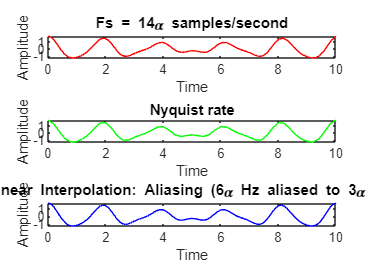


%sampling frequencies
Fs_a = 14 * alpha; % Fs = 14alpha samples/second
Fs_nyquist = 2 * max([freq_1, freq_2, freq_3]); % Nyquist rate
Fs_aliasing = 9 * alpha; % Aliasing scenario
t=0:0.0001:1;

signal_1 = alpha * cos(2 * pi * freq_1 * t);
signal_2 = (alpha / 2) * cos(2 * pi * freq_2 * t);
signal_3 = (alpha / 4) * cos(2 * pi * freq_3 * t);
signal_4 = signal_1 + signal_2 + signal_3;


% Sample the cumulative signal at different sampling frequencies
samples_a = signal_4(1 : round(Fs_a * duration) : end);
samples_nyquist = signal_4(1 : round(Fs_nyquist * duration) : end);
samples_aliasing = signal_4(1 : round(Fs_aliasing * duration) : end);

% Discrete-time waveforms using stem
time_a = linspace(0, duration, length(samples_a));
time_nyquist = linspace(0, duration, length(samples_nyquist));
time_aliasing = linspace(0, duration, length(samples_aliasing));

% Plot interpolated signals
figure;

subplot(3, 1, 1);
plot(time_a, samples_a, 'r');
title('Fs = 14\alpha samples/second');
xlabel('Time');
ylabel('Amplitude');


subplot(3, 1, 2);
plot(time_nyquist, samples_nyquist, 'g');
title('Nyquist rate');
xlabel('Time');
ylabel('Amplitude');


subplot(3, 1, 3);
plot(time_aliasing, samples_aliasing, 'b');
title('Linear Interpolation: Aliasing (6\alpha Hz aliased to 3\alpha Hz)');
xlabel('Time');
ylabel('Amplitude');

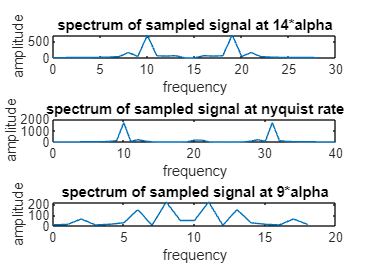

%% 5 th part in 1st question 
subplot(3,1,1)
x=fft(Y1);
fx=linspace(0,14*a,length(x));
plot(fx,abs(x).^2)
ylabel('amplitude')
xlabel('frequency')
title('spectrum of sampled signal at 14*alpha')


subplot(3,1,2)
y=fft(Y2);
fy=linspace(0,20*a,length(y));
plot(fy,abs(y).^2)
ylabel('amplitude')
xlabel('frequency')
title('spectrum of sampled signal at nyquist rate')


subplot(3,1,3)
z=fft(Y3);
fz=linspace(0,9*a,length(z));
plot(fz,abs(z).^2)
ylabel('amplitude')
xlabel('frequency')
title('spectrum of sampled signal at 9*alpha')

%%2nd question 
notes=["Do" "Re" "Mi" "Fa" "So" "La" "Ti" "Do"];
freq=[261.6 293.6 329.6 349.2 392.0 440.0 493.8 523.25];

a=[];
for n=1:8
   t=0:0.000125:1; % Note duration
   a=[a sin(2*pi*freq(n)*t)]; % Signal
end

duration=10;
fs=[15000,20000,30000,40000,44100,50000];
for n=1:length(fs)
    sound(a,fs(n));
    pause(duration);
end    

% Saving as .wav file
Fs=44100;
filename="DoReMi.wav";
audiowrite(filename,a,Fs);